# Cleaned-Up Square Conducting Analysis

Anil and Samyoung

[square_accel, square_gyro] = parsePowerSenseData_1('anil_perfect_square.csv');

% data grabbing
times = square_accel(:,1);                % grab times column
times = times-times(1);                   % center unex times
x_accel_square = square_accel(1:end,2);   % grab xaccel
z_accel_square = square_accel(1:end,4);   % grab yaccel

num = 8;
h = ones(1, num)./num;    % define convolution shape

% double moving average on z data
zacc = conv(z_accel_square, h);
zacc = zacc(1:end-length(h)+1);
zacc = conv(zacc, h);
zacc = zacc(1:end-length(h)+1);
untouchedz = zacc;

% double moving average on x data
xacc = conv(x_accel_square, h);
xacc = xacc(1:end-length(h)+1);
xacc = conv(xacc, h);
xacc = xacc(1:end-length(h)+1);

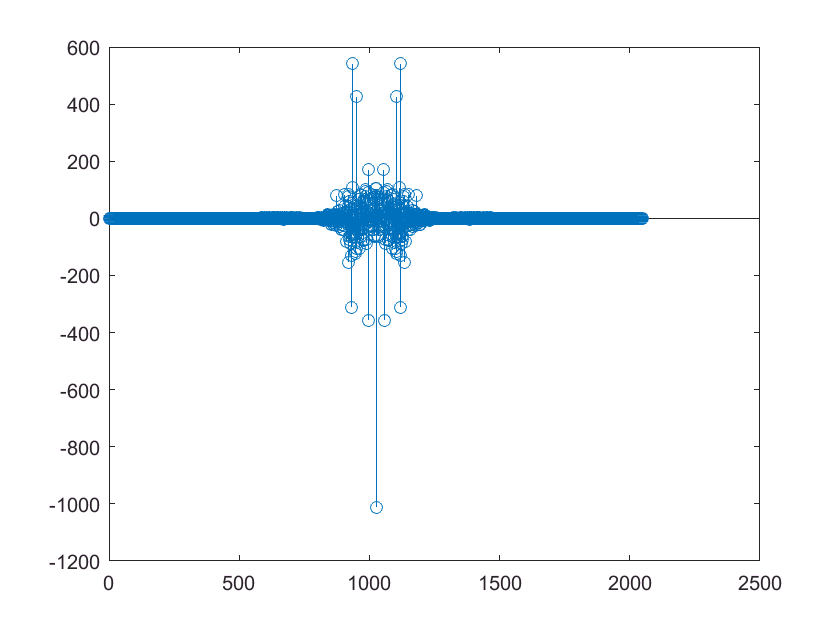

% ideal low pass filter on x data
n = -420:420;      % n parameter
wc = pi/20;        % filter frequency in rad/sec

h = wc/pi * sinc(wc*n/pi);        % define convolution shape
x_ideal = conv(xacc, h);          % convolve xacc with shape
stem(real(fftshift(fft(xacc))))   % check fft of original x

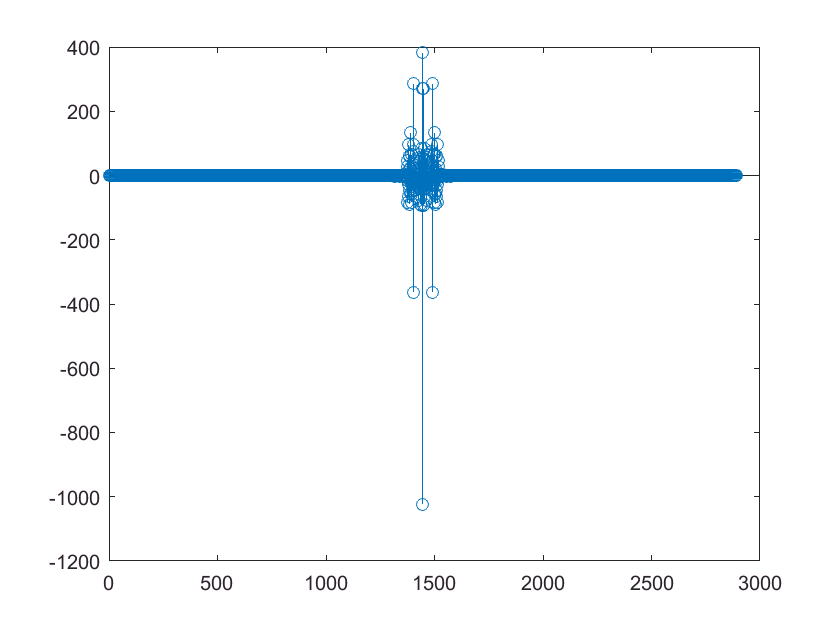

stem(real(fftshift(fft(x_ideal))))% check fft of filtered x

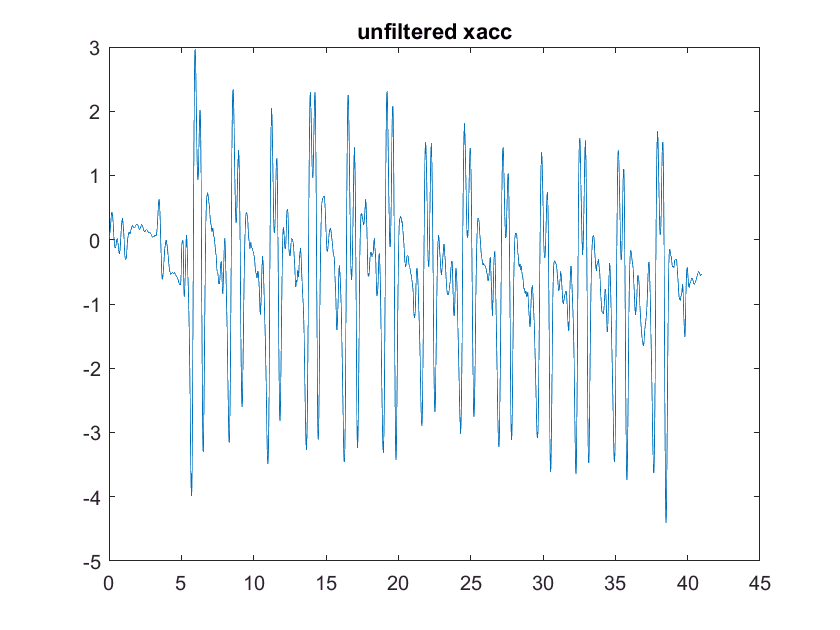


% fix convolution additions
error = (length(x_ideal)-length(xacc))/2;
x_ideal = x_ideal(error+1:end-error);

plot(times, xacc)       % plot the original xacc data
title('unfiltered xacc')

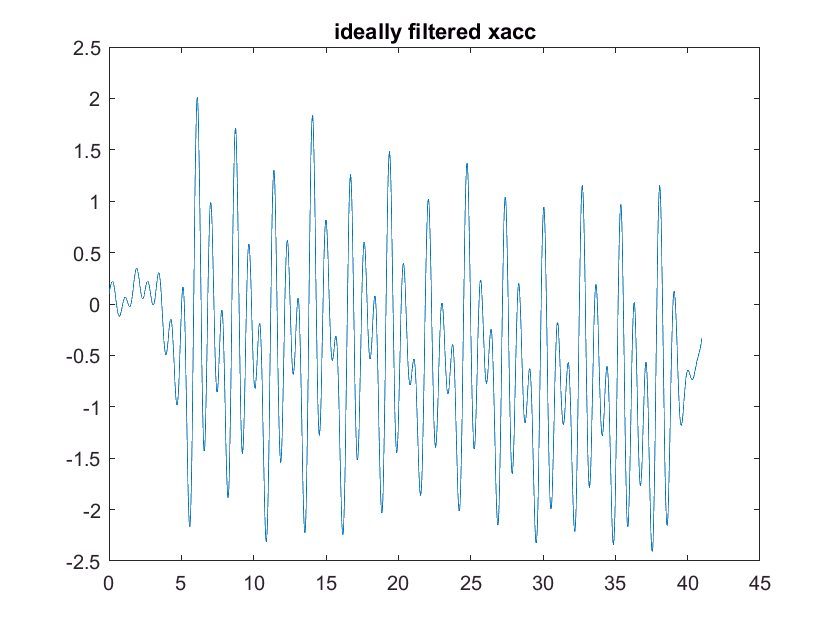

plot(times, x_ideal)    % plot the ideally filtered data
title('ideally filtered xacc')

% z acceleration beat analysis
% beat de-fuzzing
for i = 1 : size(zacc)-4
    if(abs((zacc(i)- 9.81) < 1) && (abs((zacc(i + 2)- 9.81))< 1))
        zacc(i) = 9.81;
    end
end

% initialize some arrays
beatOne = [];
beatThree = [];

% Loop through all zaccels, find ones and threes
for i = 3 : size(zacc)-4
    % beat one checker
    if((zacc(i)== 9.81) && (zacc(i-1)- 9.81 >0) && (zacc(i+ 1)== 9.81))
        beatOne = cat(1, beatOne, i);
    end
    
    % beat three checker
    if((zacc(i)== 9.81) && (zacc(i+1)- 9.81 >0) && (zacc(i- 1)== 9.81))
         beatThree = cat(1, beatThree, i);
    end
end

% Use xaccel to find beat two
binarySignal = x_ideal>0.8;
leadingEdges2 = find(diff(binarySignal) >= 1);
beatTwo = leadingEdges2;
correc = 0.1;

fours = [];
index = 1;

% use local maximums to find beat 4
[pks, locs] = findpeaks(zacc);

for i = 1:length(pks)
    if pks(i) < 8.1
        fours(index) = locs(i);
        index = index+1;
    end
end

beatFour = fours(3:end);
beatFourTimes = times(beatFour);

% Uses indexes to find timestamps
beatOne = beatOne(1:end-1)

beatOne =          270
         402
         532
         664
         797
         935
        1067
        1201
        1334
        1463


beatOneTimes = times(beatOne)

beatOneTimes =     5.3806
    8.0209
   10.6212
   13.2615
   15.9218
   18.6821
   21.3224
   24.0027
   26.6630
   29.2433



good_times = [1 3:5 7:15];
beatTwo = beatTwo(good_times);
beatTwoTimes = times(beatTwo)+correc

beatTwoTimes =     6.0007
    8.6610
   11.3613
   13.9816
   16.6619
   19.3222
   22.0825
   24.7028
   27.3831
   30.0834



beatThree = beatThree(2:end);
beatThreeTimes = times(beatThree)

beatThreeTimes =     6.8008
    9.4211
   12.0214
   14.6617
   17.4820
   20.0623
   22.7626
   25.4429
   28.0232
   30.7235


zacc_squash = zacc;
zacc = zacc-9.81;

% distance integrations
% beat 1
dist_ints1 = zeros(1, length(beatOne)-1);

for i = 1:length(beatOne)-1
    start_temp = beatFour(i);
    end_temp = beatOne(i+1);
    
    times_temp = times(start_temp:end_temp);
    zacc_temp = zacc(start_temp:end_temp);
   
    velocity = cumtrapz(times_temp, zacc_temp);
    position = trapz(times_temp, velocity);
    dist_ints1(i) = position;    
end

% beat 2
dist_ints2 = zeros(1, length(beatTwo)-1);

for i = 1:length(beatTwo)-1
    start_temp = beatOne(i);
    end_temp = beatTwo(i);
    
    times_temp = times(start_temp:end_temp);
    xacc_temp = xacc(start_temp:end_temp);
        
    velocity = cumtrapz(times_temp, xacc_temp);
    % figure()
    % plot(times_temp, velocity)
    position = trapz(times_temp, velocity);
    
    dist_ints2(i) = position;
end

% beat 3
dist_ints3 = zeros(1, length(beatThree)-1);

for i = 1:length(beatThree)-1
    start_temp = beatTwo(i);
    end_temp = beatThree(i);
    
    times_temp = times(start_temp:end_temp);
    xacc_temp = xacc(start_temp:end_temp);
        
    velocity = cumtrapz(times_temp, xacc_temp);
    % figure
    % plot(times_temp, xacc_temp)
    position = trapz(times_temp, velocity);
    
    dist_ints3(i) = position;
end


% beat 4
dist_ints4 = zeros(1, length(beatThree)-1);

for i = 1:length(beatFour)-1
    start_temp = beatThree(i);
    end_temp = beatFour(i);
    
    times_temp = times(start_temp:end_temp);
    zacc_temp = zacc(start_temp:end_temp);
        
    velocity = cumtrapz(times_temp, zacc_temp);
    % figure
    % plot(times_temp, zacc_temp)
    position = trapz(times_temp, velocity);
    
    dist_ints4(i) = position;
end

% conversion
m2in = 39.3701;
za = zeros(1, length(dist_ints1));
dist1 = [za; dist_ints1.*m2in];
dist2 = [dist_ints2.*m2in; za];
dist3 = [dist_ints3.*m2in; za];
dist4 = [za; dist_ints4.*m2in];

% chop last 2
dist1 = dist1(:, 1:end-2);
dist2 = dist2(:, 1:end-2);
dist3 = dist3(:, 1:end-2);
dist4 = dist4(:, 1:end-2);

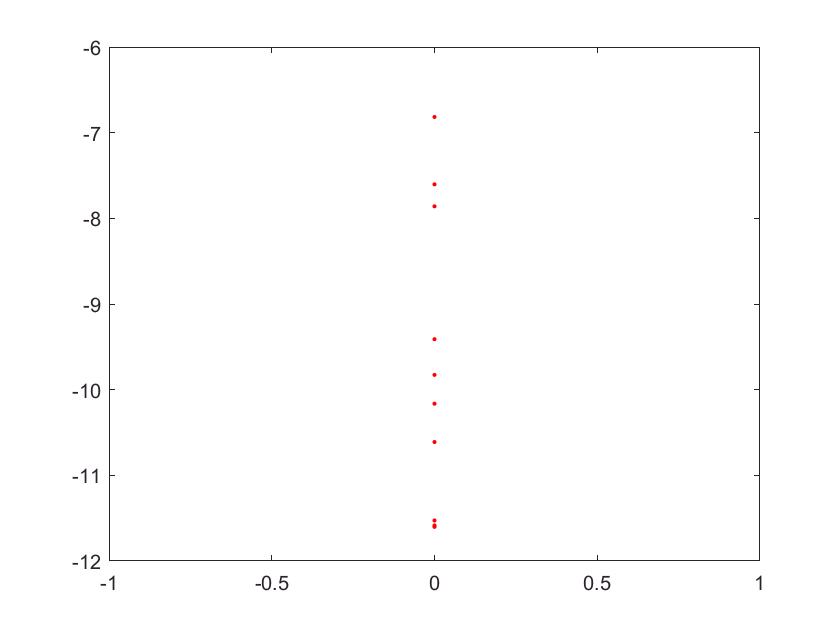

% make a graph of conducting plot
figure
hold on
plot(dist1(1,:), dist1(2,:), 'r.')

plot(dist1(1,:), dist1(2,:), 'r.')
plot(dist2(1,:), dist2(2,:), 'r.')
plot(dist3(1,:), dist3(2,:), 'r.')
plot(dist4(1,:), dist4(2,:), 'r.')


% find beat lengths
onetotwo = beatTwoTimes-beatOneTimes;
twotothree = beatThreeTimes-beatTwoTimes;
threetofour = beatFourTimes-beatThreeTimes;

% analyzing distances
% find averages
dist1_avg = sum(dist1(2,:)/length(dist1(2,:)))

dist1_avg = -9.7006

dist2_avg = sum(dist2(1,:)/length(dist2(1,:)))

dist2_avg = -11.0600

dist3_avg = sum(dist3(1,:)/length(dist3(1,:)))

dist3_avg = 4.9796

dist4_avg = sum(dist4(2,:)/length(dist4(2,:)))

dist4_avg = 10.5340


% find unsigned errors
dist1_err = abs(abs(dist1_avg-dist1(2,:))/dist1_avg);
dist2_err = abs(abs(dist2_avg-dist2(1,:))/dist2_avg);
dist3_err = abs(abs(dist3_avg-dist3(1,:))/dist3_avg);
dist4_err = abs(abs(dist4_avg-dist4(2,:))/dist4_avg);

% find signed errors
sdist1_err = dist1_avg-dist1(2,:)/dist1_avg;
sdist2_err = dist2_avg-dist2(1,:)/dist2_avg;
sdist3_err = dist3_avg-dist3(1,:)/dist3_avg;
sdist4_err = dist4_avg-dist4(2,:)/dist4_avg;

% find avg errors
err1avg = mean(dist1_err)

err1avg = 0.1466

err2avg = mean(dist2_err)

err2avg = 0.1669

err3avg = mean(dist3_err)

err3avg = 1.0740

err4avg = mean(dist4_err)

err4avg = 0.0606


% consistency
const1 = 1-err1avg

const1 = 0.8534

const2 = 1-err2avg

const2 = 0.8331

const3 = 1-err3avg

const3 = -0.0740

const4 = 1-err4avg

const4 = 0.9394

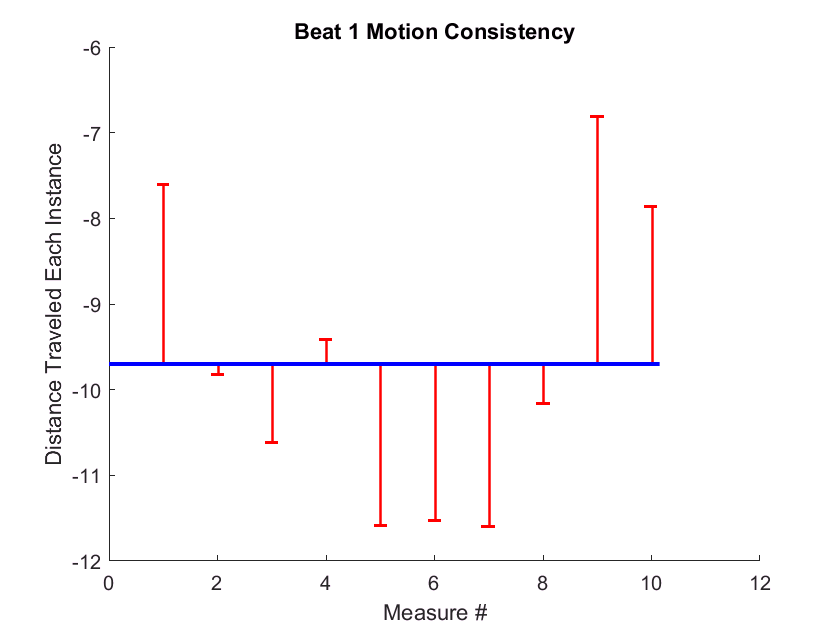

% plot error
% beat 1 error
err1 = dist1_avg-dist1(2,:);
err1neg = [-2.097100000000000,0,0,-0.289300000000000,0,0,0,0,-2.883900000000000,-1.840600000000000];
err1pos = [0,0.126700000000000,0.910300000000000,0,1.884000000000000,1.825900000000000,1.901000000000000,0.463000000000000,0,0];
avg1 = dist1_avg.*ones(1, length(err1));
err2 = dist2_avg-dist2(1,:);
err3 = dist3_avg-dist3(1,:);
err4 = dist4_avg-dist4(2,:);

x = 1:length(err1);

% neg = zeros(1,length(err1));
figure
hold on
errorbar(x, avg1, err1pos, err1neg, 'r.', 'linewidth', 1.25, 'MarkerSize',2,'MarkerEdgeColor','b','MarkerFaceColor','b')
plot([0 10.15], [dist1_avg dist1_avg], 'b', 'linewidth', 2)
title('Beat 1 Motion Consistency')
xlabel('Measure #')
ylabel('Distance Traveled Each Instance')

% 
% errorbar(x,y,err,'-s','MarkerSize',10,...
%     'MarkerEdgeColor','red','MarkerFaceColor','red')

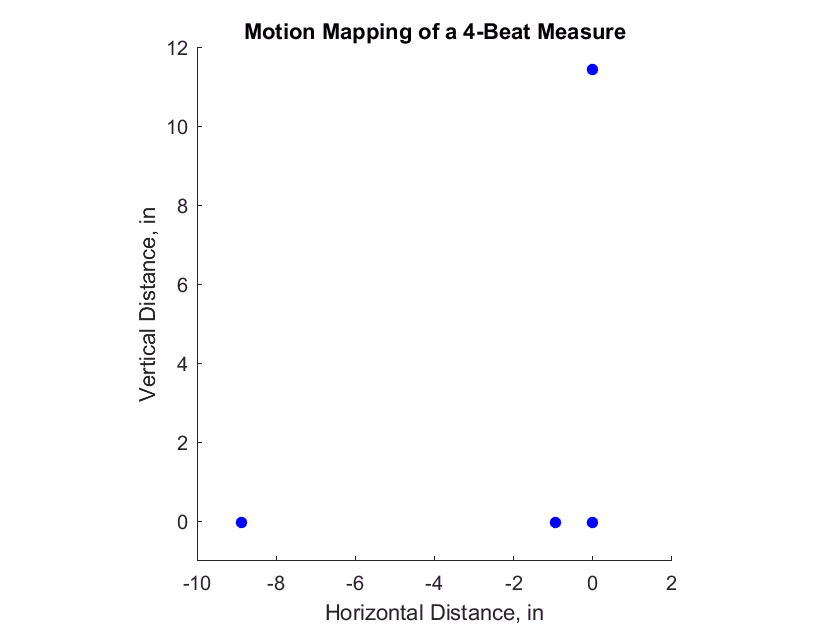

% Plot a path for 1 beat
clf
hold on
mov1 = dist1(:,6);
mov2 = dist2(:,6);
mov3 = dist3(:,6);
mov4 = dist4(:,6);
zero = [0;0];
sz = 20;

plot(mov1(1), mov1(2)+11.5,'b.', 'markersize', sz)
plot(mov2(1), mov1(2)+11.5,'b.', 'markersize', sz)
plot(mov2(1)+mov3(1)+1, mov1(2)+11.5,'b.', 'markersize', sz)
plot(mov4(1), mov1(2)+mov4(2)+11.5,'b.', 'markersize', sz)
axis('equal')
axis([-10 2 -1 12])
title('Motion Mapping of a 4-Beat Measure')
xlabel('Horizontal Distance, in')
ylabel('Vertical Distance, in')

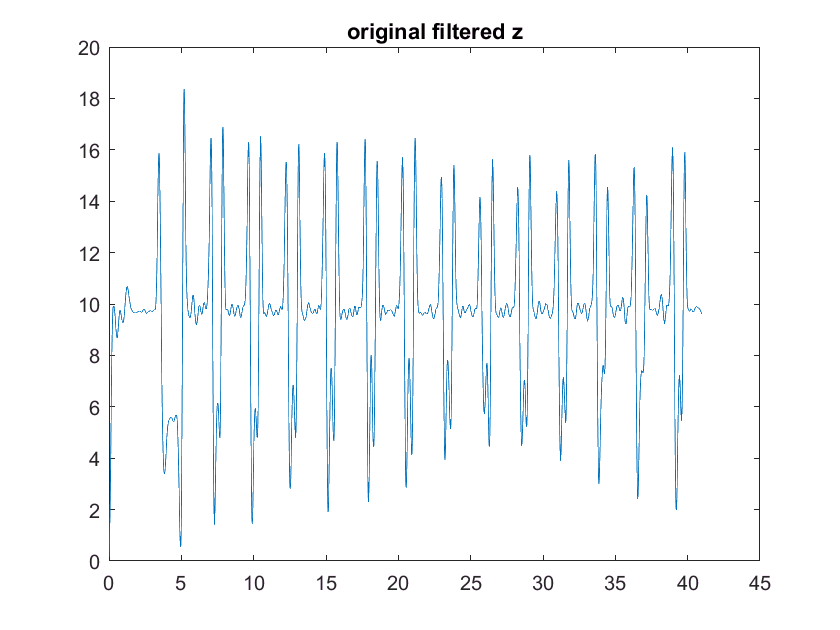

% visualize all data
plot(times,untouchedz)
title('original filtered z')

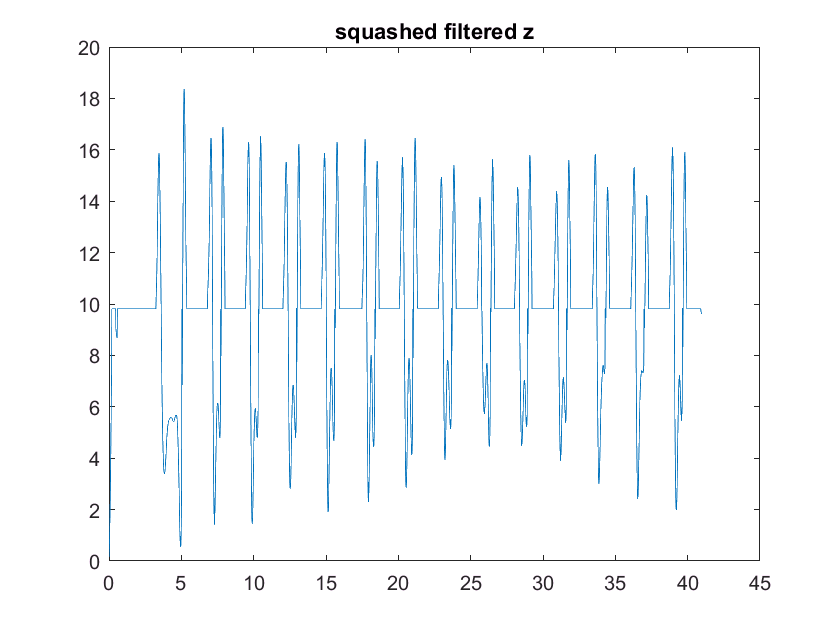

plot(times,zacc_squash)
title('squashed filtered z')

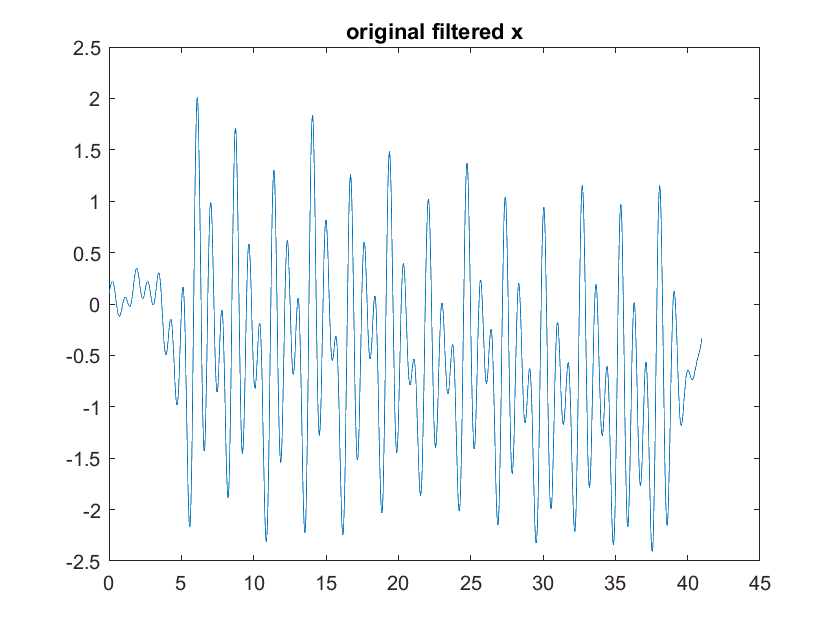

plot(times,x_ideal)
title('original filtered x')